# Set Data

load('forclass.mat') 
H = GenWeird(64,5,3);
x = 1:64; 
img = img(150,x)'; 

## Pass Images through system

g = H*img;

## Calculate SVD

[V,D,Ut] = svd(H);

## Plot results

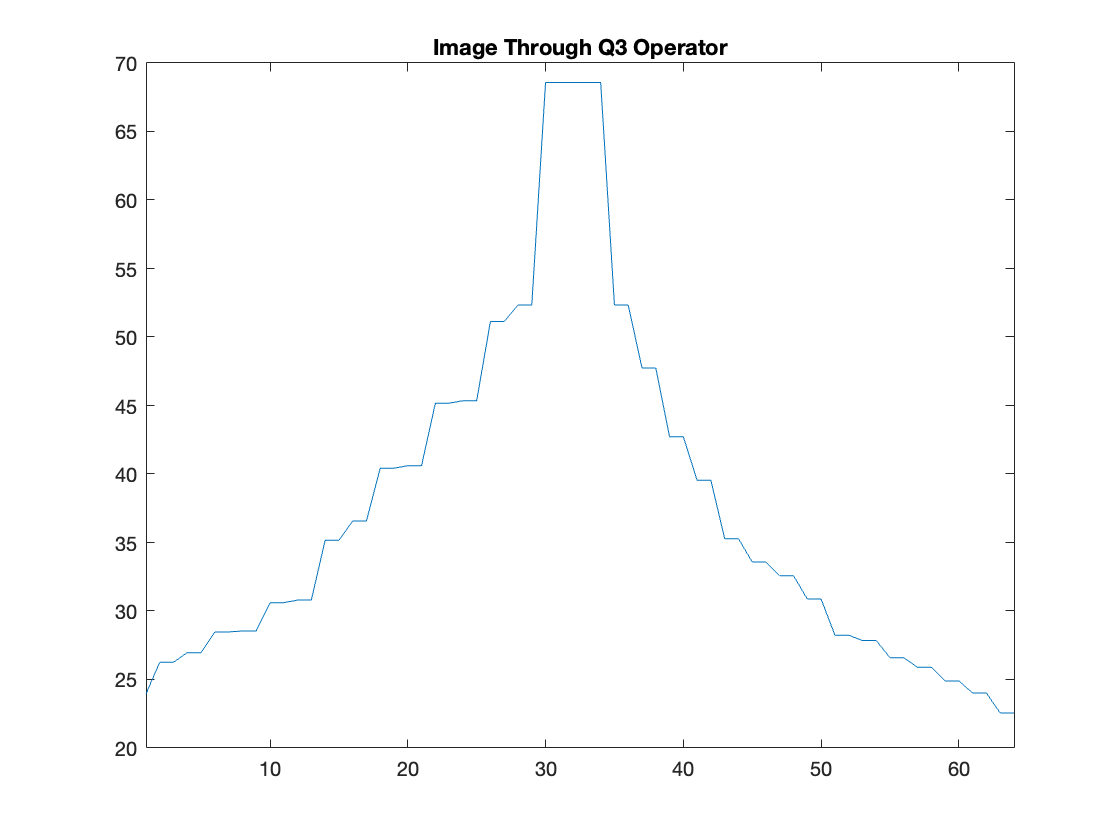

figure('Color', 'w')
plot(x,g)
title('Image Through Q3 Operator')
xlim([1 64])

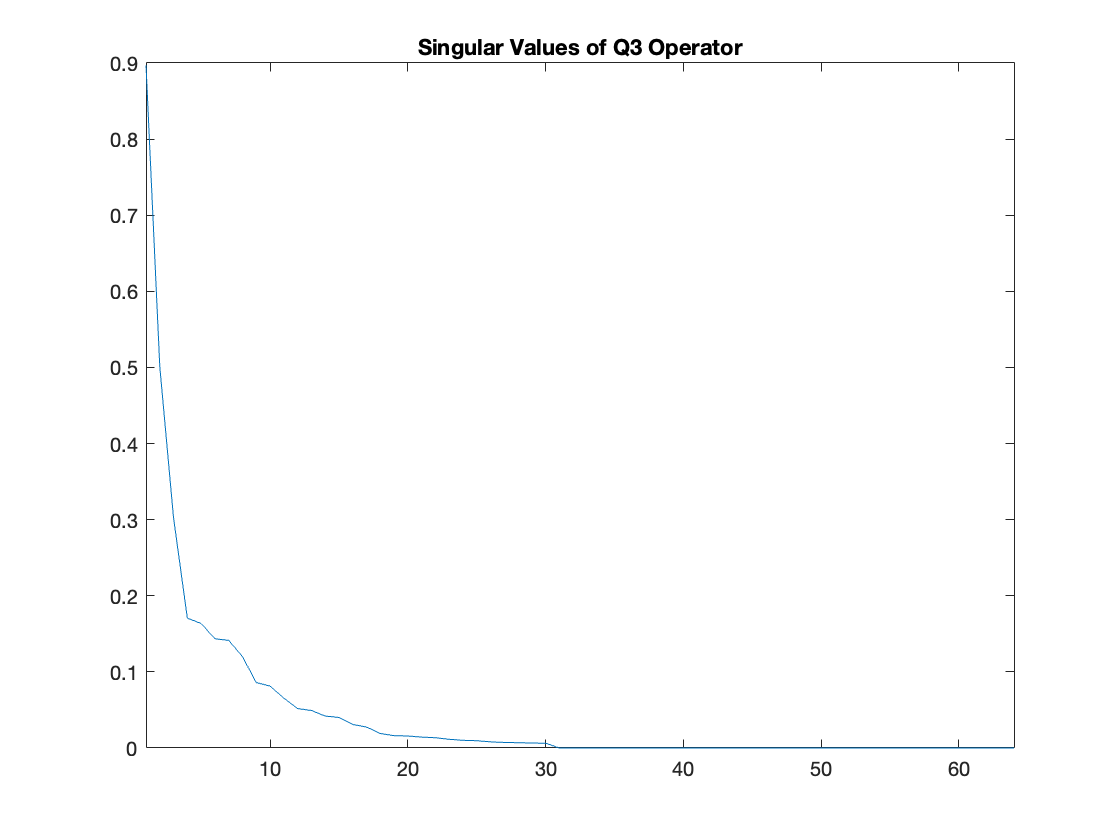


figure('Color', 'w')
plot(x,diag(D))
title('Singular Values of Q3 Operator')
xlim([1 64])

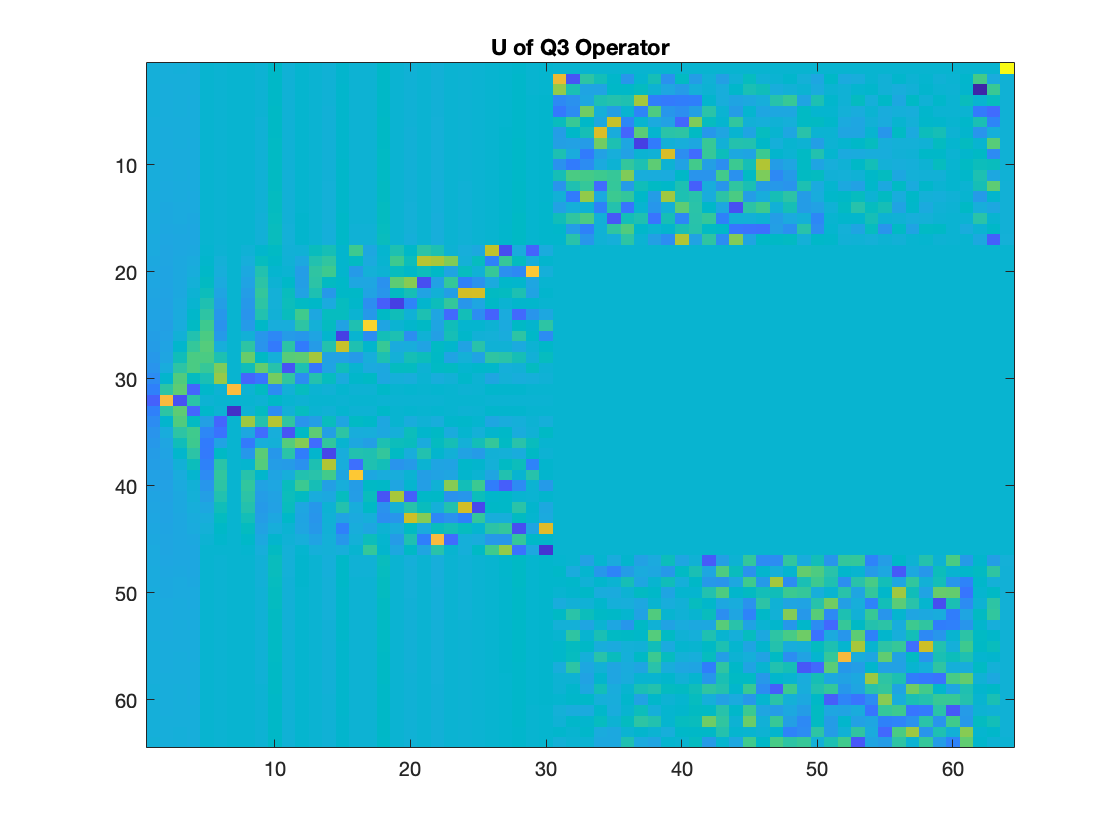


figure('Color', 'w')
imagesc(Ut)
title('U of Q3 Operator')

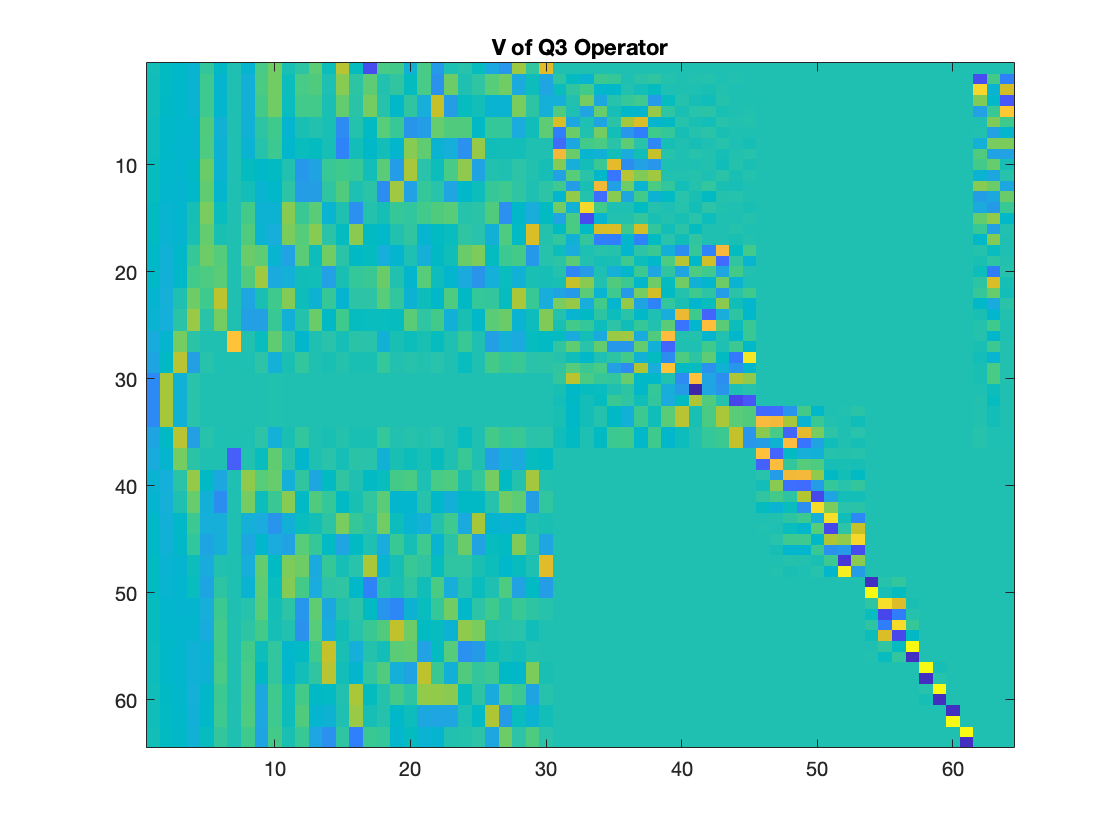


figure('Color', 'w')
imagesc(V)
title('V of Q3 Operator')